%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Modelling Yield Curves and Forward Rates; 
%  Author:      Carpenter, William
%  Created:     March 10th, 2021
%  Last Edited: March 28nd, 2021

% Link to data (updated daily): 
% https://www.treasury.gov/resource-center/data-chart-center/interest-rates/pages/textview.aspx?data=yield

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Exploring Par Yield Data; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    % Read in par yield curve data 
    clear;
    clc;
    
    % Read in par yield curve data
    % The file in is *.csv format
    cd '/MATLAB Drive/Fixed Income Models';
    y      = readtable('onTheRunTreasuries.csv');
    yields = table2array(y(1:end, 5:end)).*1/100;
    date   = datetime(y.year, y.month, y.day);
    
    % Most recent 10-days of yield curve data 
    display(y(end-10:end,:));

  11×16 table

    year    month    day    dateString    oneMonth    twoMonth    threeMonth    sixMonth    oneYear    twoYear    threeYear    fiveYear    sevenYear    tenYear    twentyYear    thirtyYear
    ____    _____    ___    __________    ________    ________    __________    ________    _______    _______    _________    ________    _________    _______    __________    __________

  

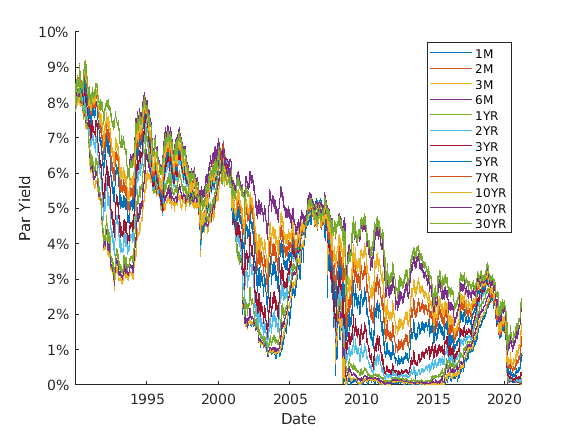

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Par Yields Time Series;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% 2-dimentional graph of various par yields (1m, 2m, ... 30y)
    
    % Most recent constant maturity yield curve
    clf
    hold on 
            plot(date, y.oneMonth);
            plot(date, y.twoMonth);
            plot(date, y.threeMonth);
            plot(date, y.sixMonth);
            plot(date, y.oneYear);
            plot(date, y.twoYear);
            plot(date, y.threeYear);
            plot(date, y.fiveYear);
            plot(date, y.sevenYear);
            plot(date, y.tenYear);
            plot(date, y.twentyYear);
            plot(date, y.thirtyYear);
            % legend('oneMonth', 'NLS Fitted Prices (w/ Nelson-Siegel)')
            %title('Constant Maturity Treasury Rates 1990 - 2021')
            ytickformat('percentage')
            legend('1M', '2M', '3M', '6M', '1YR', '2YR', '3YR', '5YR', '7YR' ...
                , '10YR', '20YR', '30YR')
            ylabel('Par Yield')
            xlabel('Date')
            legend('Location','northeast')
    hold off